%% Step 1: Load and Normalize Data
data = readtable("C:\Users\R RAMKUMAR\Downloads\temperature.csv");  % Make sure this path is correct
temperature = data{:, 2};             % Assuming 2nd column is temperature

% Normalize between 0 and 1
temp_min = min(temperature);
temp_max = max(temperature);
temp_normalized = (temperature - temp_min) / (temp_max - temp_min);

%% Step 2: Create Input-Output Sequences
sequenceLength = 10;
X = {};
Y = {};

for i = 1:length(temp_normalized) - sequenceLength
    X{i} = temp_normalized(i:i+sequenceLength-1)';  % [10, 1]
    Y{i} = temp_normalized(i+sequenceLength);       % scalar target
end

%% Step 3: Split into Train and Test
numSamples = length(X);
numTrainVal = floor(0.7 * numSamples);   % 70% for training and validation
numTest = numSamples - numTrainVal;      % 30% for testing

% Train/test split
XTrain = X(1:numTrainVal);
YTrain = reshape(cell2mat(Y(1:numTrainVal)), [], 1);
XTest = X(numTrainVal+1:end);            % Test Data
YTest = reshape(cell2mat(Y(numTrainVal+1:end)), [], 1);

%% Step 4: Add Small Noise to XTrain (optional)
noise = 0.01 * randn(size(YTrain));
for i = 1:length(XTrain)
    XTrain{i} = XTrain{i} + noise(i);  % additive Gaussian noise
end

%% Step 5: Define 1D CNN Architecture
layers = [
    sequenceInputLayer(1, 'MinLength', sequenceLength)
    convolution1dLayer(3, 16, 'Padding', 'same')
    reluLayer
    maxPooling1dLayer(2, 'Stride', 2)
    convolution1dLayer(3, 32, 'Padding', 'same')
    reluLayer
    globalMaxPooling1dLayer
    dropoutLayer(0.2)
    fullyConnectedLayer(50)
    reluLayer
    dropoutLayer(0.2)
    fullyConnectedLayer(1)
    regressionLayer
];

%% Step 6: Define Training Options
options = trainingOptions('adam', ...
    'MaxEpochs', 100, ...
    'MiniBatchSize', 32, ...
    'InitialLearnRate', 0.001, ...
    'Shuffle', 'never', ...
    'ValidationData', {XTest, YTest}, ... % Optional, can still use test data for validation
    'ValidationFrequency', 30, ...
    'ValidationPatience', 50, ...
    'Verbose', 1, ...
    'Plots', 'training-progress');

%% Step 7: Train Network
rng(1);  % for reproducibility
disp("Training 1D CNN model...");

Training 1D CNN model...


Training on single CPU.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     RMSE     |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:03 |         0.34 |         0.58 |       0.0564 |       0.1674 |          0.0010 |
|       1 |          30 |       00:00:03 |         0.22 |         0.10 |       0.0240 |       0.0053 |          0.0010 |
|       2 |          50 |       00:00:04 |         0.22 |              |       0.0234 |              |          0.0010 |
|       2 |          60 |       00:00:04 |         0.17 |         0.10 |       0.0146 |       0.0055 |          0.0010 |
|       

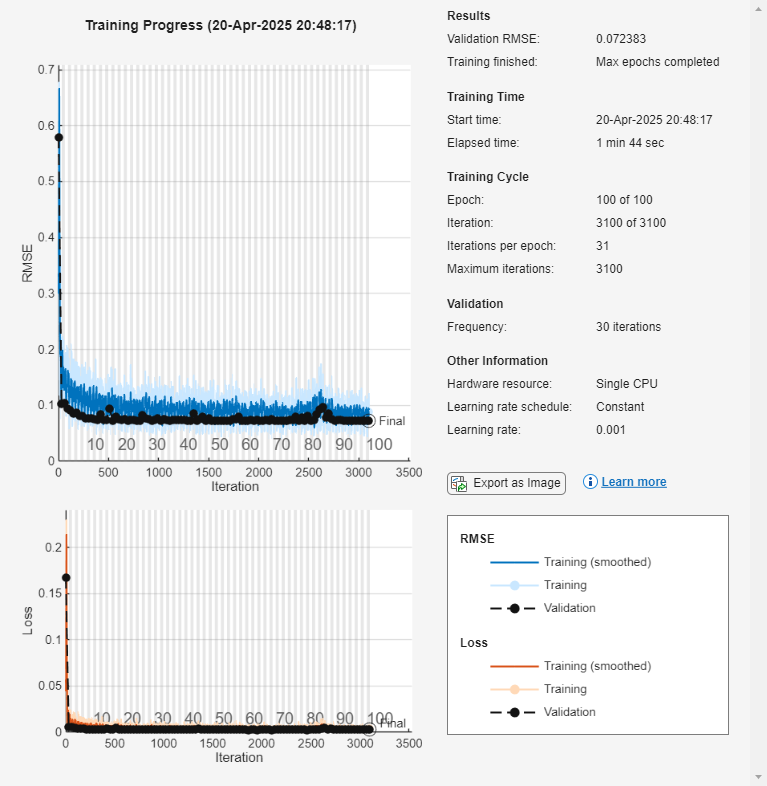

net = trainNetwork(XTrain, YTrain, layers, options);

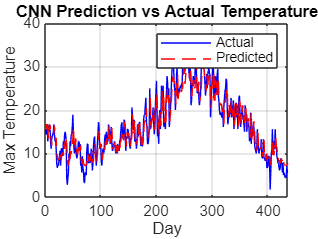


%% Step 8: Predict on Train and Test Set and Rescale
YPredTrain = predict(net, XTrain);
YPredTest = predict(net, XTest);

% Rescale predictions and actual values back to original temperature scale
YPredTrain_rescaled = YPredTrain * (temp_max - temp_min) + temp_min;
YPredTest_rescaled = YPredTest * (temp_max - temp_min) + temp_min;

YTrain_rescaled = YTrain * (temp_max - temp_min) + temp_min;
YTest_rescaled = YTest * (temp_max - temp_min) + temp_min;

%% Step 9: Plot Results (Test Set)
figure;
plot(YTest_rescaled, 'b', 'DisplayName', 'Actual');
hold on;
plot(YPredTest_rescaled, 'r--', 'DisplayName', 'Predicted');
xlabel('Day');
ylabel('Max Temperature');
legend;
title('CNN Prediction vs Actual Temperature');
grid on;


%% Step 10: Calculate RMSE and R-squared (Train and Test)
% RMSE Calculation Function
rmse = @(yTrue, yPred) sqrt(mean((yPred - yTrue).^2));

% R-squared Calculation Function
rSquared = @(yTrue, yPred) 1 - sum((yTrue - yPred).^2) / sum((yTrue - mean(yTrue)).^2);

% Calculate RMSE and R-squared for Train and Test Sets
rmseTrain = rmse(YTrain_rescaled, YPredTrain_rescaled);
r2Train = rSquared(YTrain_rescaled, YPredTrain_rescaled);

rmseTest = rmse(YTest_rescaled, YPredTest_rescaled);
r2Test = rSquared(YTest_rescaled, YPredTest_rescaled);

%% Step 11: Print all metrics
fprintf('\n--- Training Metrics ---\n');


--- Training Metrics ---


fprintf('RMSE: %.4f\n', rmseTrain);

RMSE: 2.8110


fprintf('MAE:  %.4f\n', mean(abs(YPredTrain_rescaled - YTrain_rescaled)));  % Added MAE calculation

MAE:  2.2199


fprintf('R²:   %.4f\n', r2Train);

R²:   0.8555



fprintf('\n--- Test Metrics ---\n');


--- Test Metrics ---


fprintf('RMSE: %.4f\n', rmseTest);

RMSE: 2.6927


fprintf('MAE:  %.4f\n', mean(abs(YPredTest_rescaled - YTest_rescaled)));  % Added MAE calculation

MAE:  2.1650


fprintf('R²:   %.4f\n', r2Test);

R²:   0.8612
